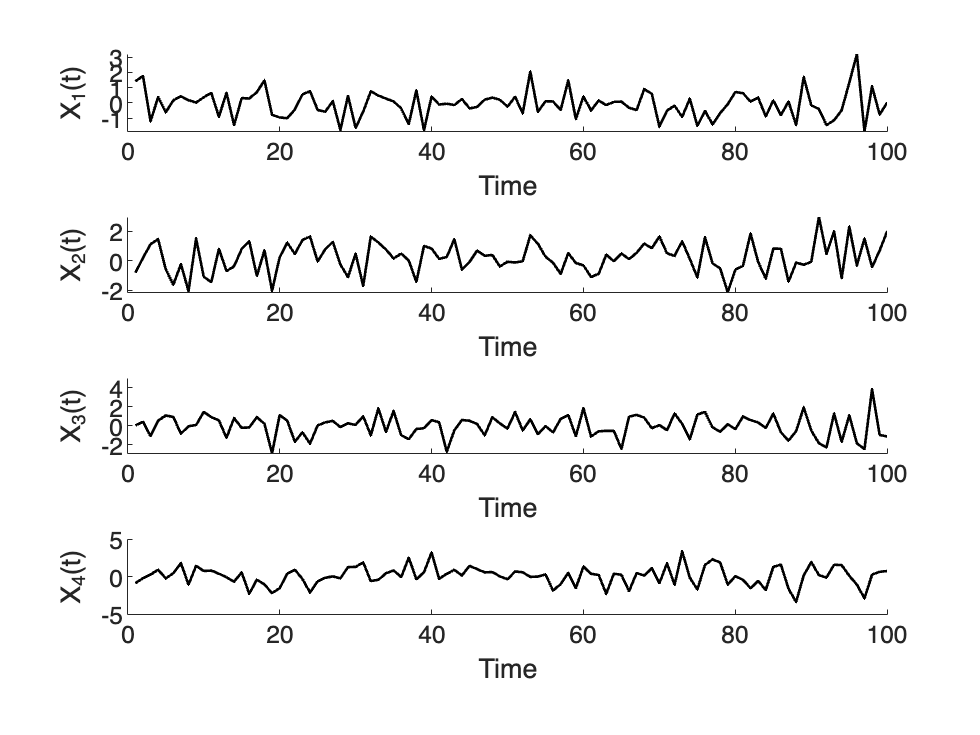

%% Granger Causality 
% (C) 2025 Moo K. Chung
% University of Wisconsin-Madison
% mkchung@wisc.edu

%% Set random seed for reproducibility. 
%% Otherwise, your simulation will be constantly changing
rng(1); 

%% Step 1: Generate Random Multivariate Time Series
%% based on VAR(p). 

% Simulated data is blind to end users
% Define true VAR(3) process to generate structured data
N=4; % Number of time series (dimensions)
T=100; % Number of time points
P=2; % Order of the VAR model
noise_level = 1;
[X, A_true] = VAR_simulate(N, T, P, noise_level);

% Display simulted time series
VAR_plot(X, 'k')

A_true

A_true = A_true(:,:,1) =

         0         0         0         0
         0         0         0         0
   -0.3034   -0.2235         0   -0.0971
   -0.4438    0.0714    0.3201         0


A_true(:,:,2) =

     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


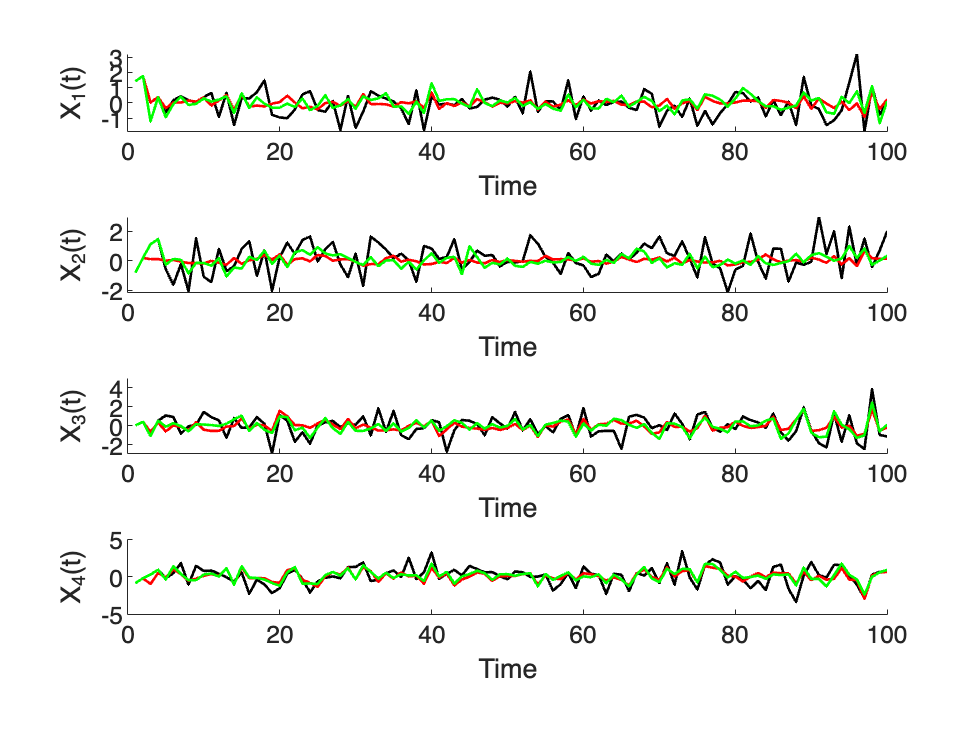


% Estimate wtih VAR model
%% We combine all the above steps into a function
[A_est, X_pred, GC_matrix] = VAR_fit(X, 2);
hold on; VAR_plot(X_pred, 'r')

[A_est, X_pred, GC_matrix] = VAR_fit(X, 4);
hold on; VAR_plot(X_pred, 'g')

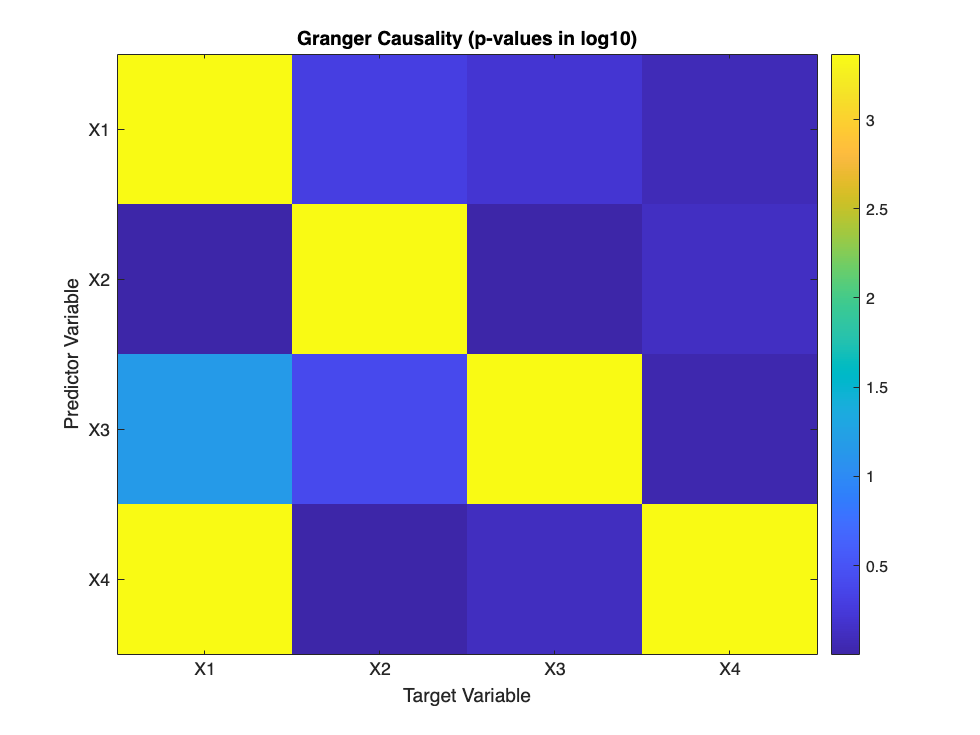

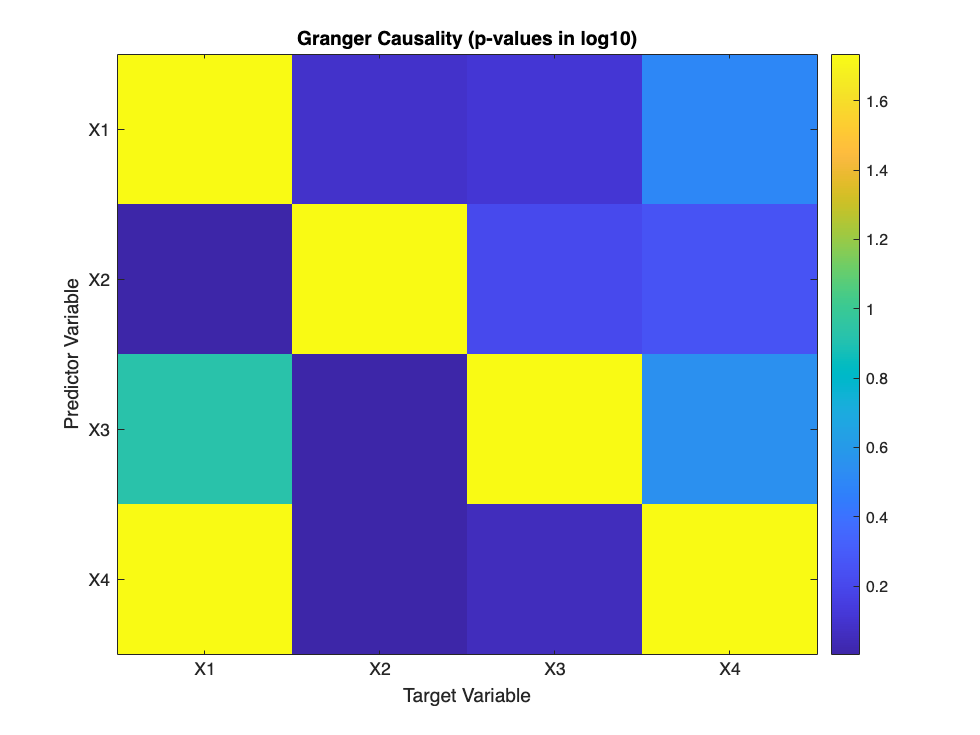


% Plot Granger causality results
figure; imagesc(GC_matrix);
colorbar;

figure;
imagesc(-log10(GC_matrix));
colorbar;
title('Granger Causality (p-values in log10)');
xlabel('Target Variable'); ylabel('Predictor Variable');
xticks(1:N); yticks(1:N);
xticklabels(strcat('X', string(1:N))); yticklabels(strcat('X', string(1:N)));


%% Application to rs-fMRI signals (6 regions)

load rsfMRI.mat

[T, N, ~] = size(rsfMRI)

T = 1200

N = 6

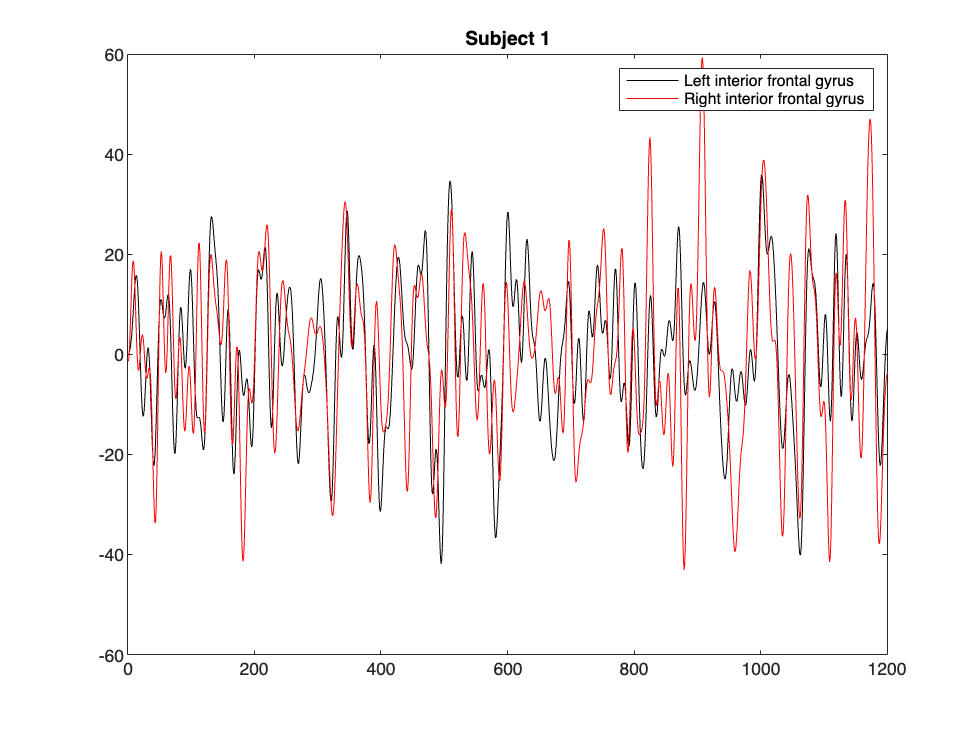

%=    time points    regions    subjects
%        1200           6         100

figure; plot(rsfMRI(:,1,1), 'k'); 
hold on; plot(rsfMRI(:,2,1), 'r');
legend('Left interior frontal gyrus', 'Right interior frontal gyrus')
title('Subject 1')

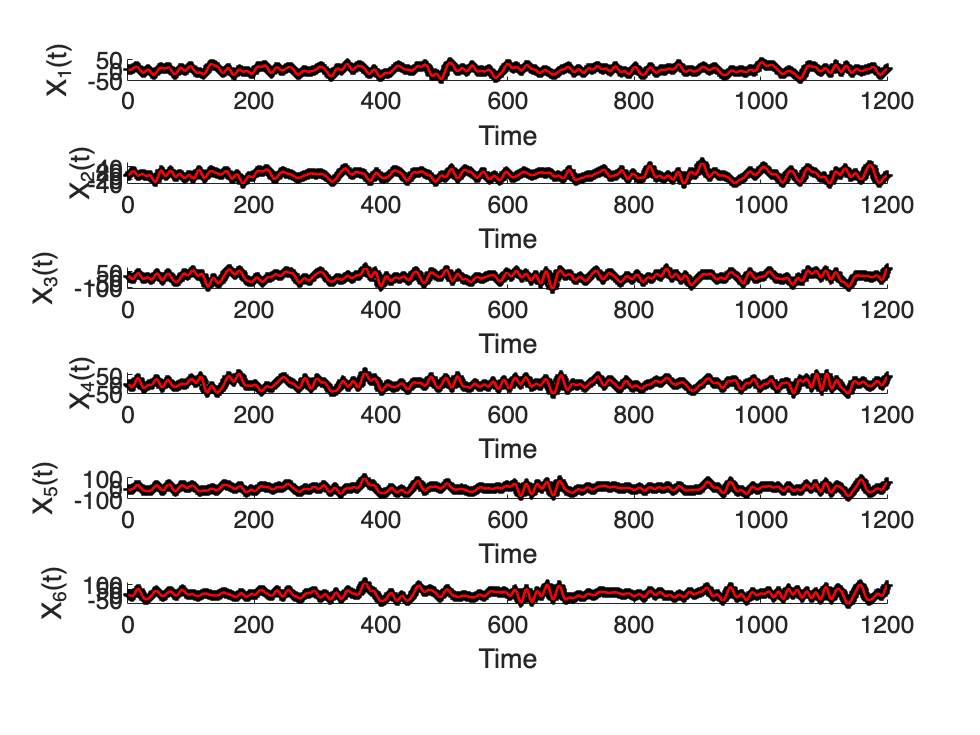



X = rsfMRI(:,:,1); 
%size(X)
%ans =
%        1200           6

X=X';
P=3;
[A_est, X_pred, GC_matrix] = VAR_fit(X, P);

figure; VAR_plot(X, '+k');
hold on; VAR_plot(X_pred, 'r')


%Fitting error in terms of Mean Squared Error (MSE)
MSE = mean(mean((X(:, P+1:T) - X_pred(:, P+1:T)).^2))

MSE = 0.0859

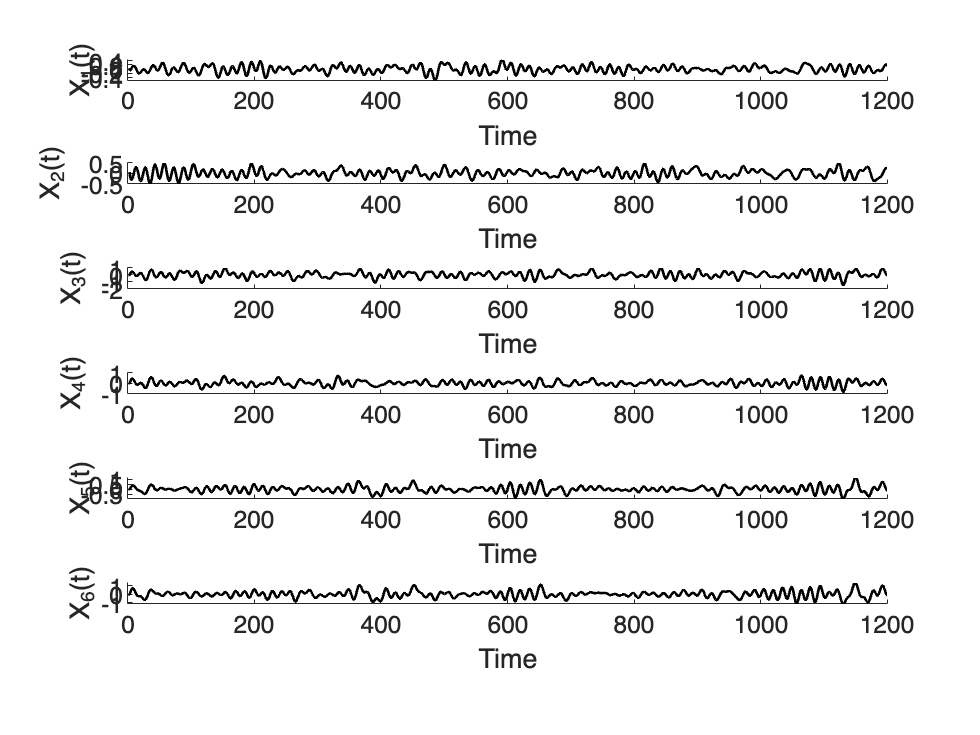


%Resisual error
figure; VAR_plot(X-X_pred, '-k');

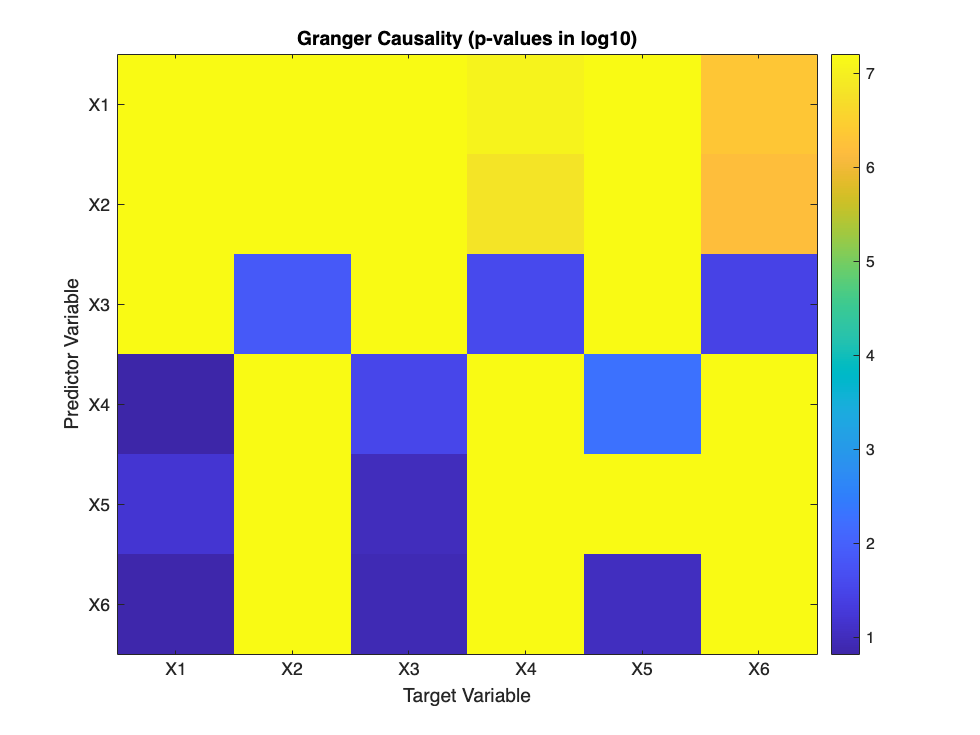


%Granger Causality
figure;
imagesc(-log10(GC_matrix));
colorbar;
title('Granger Causality (p-values in log10)');
xlabel('Target Variable'); ylabel('Predictor Variable');
xticks(1:N); yticks(1:N);
xticklabels(strcat('X', string(1:N))); yticklabels(strcat('X', string(1:N)));

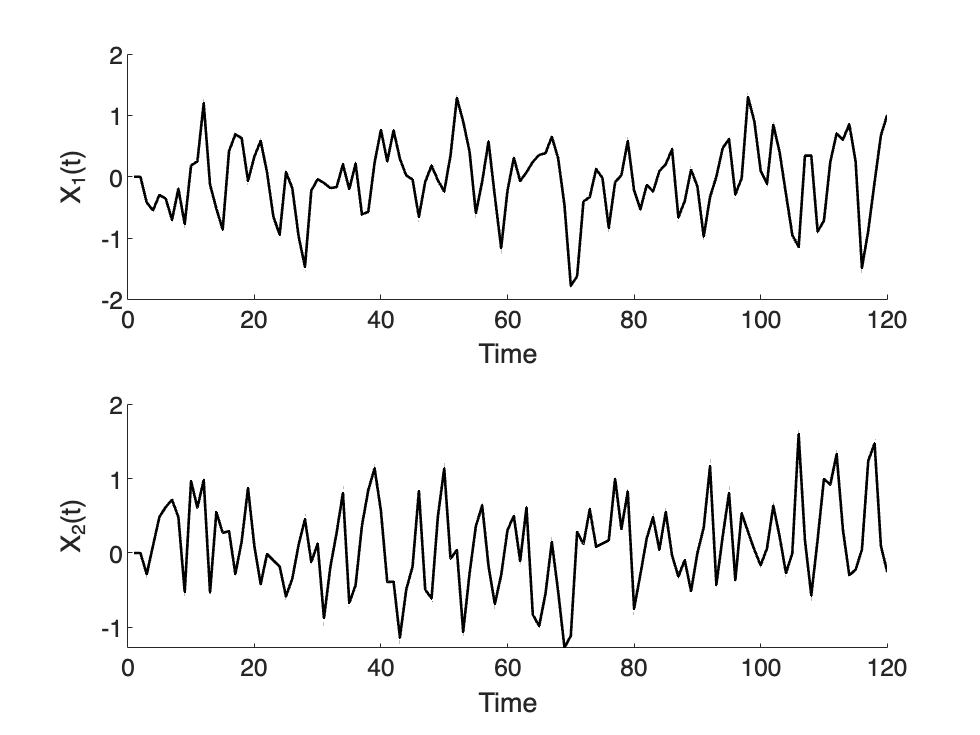


% Exercise: So far we only did model fit. See if you can use
% the method to do prediction of future event. 
% Observing time points 1 to 1100, can you predict time points
% 1101 to 1200?



clear; clc; rng(1); % Set random seed for reproducibility

% Define parameters
N = 2;  % Number of time series
T = 100; % Total time points
P = 2;  % Order of VAR model
T_future = 120; % Extend for future prediction

% Define true VAR(2) coefficient matrices
A1 = [0.5, 0.2; -0.3, 0.4]; % Lag-1 coefficients
A2 = [-0.2, 0.1; 0.1, -0.1]; % Lag-2 coefficients

% Generate Gaussian noise
epsilon = 0.5 * randn(N, T_future);

% Initialize time series
X = zeros(N, T_future);

% Simulate VAR(2) process
for t = P+1:T_future
    X(:, t) = A1 * X(:, t-1) + A2 * X(:, t-2) + epsilon(:, t);
end

figure; VAR_plot(X, '-k');

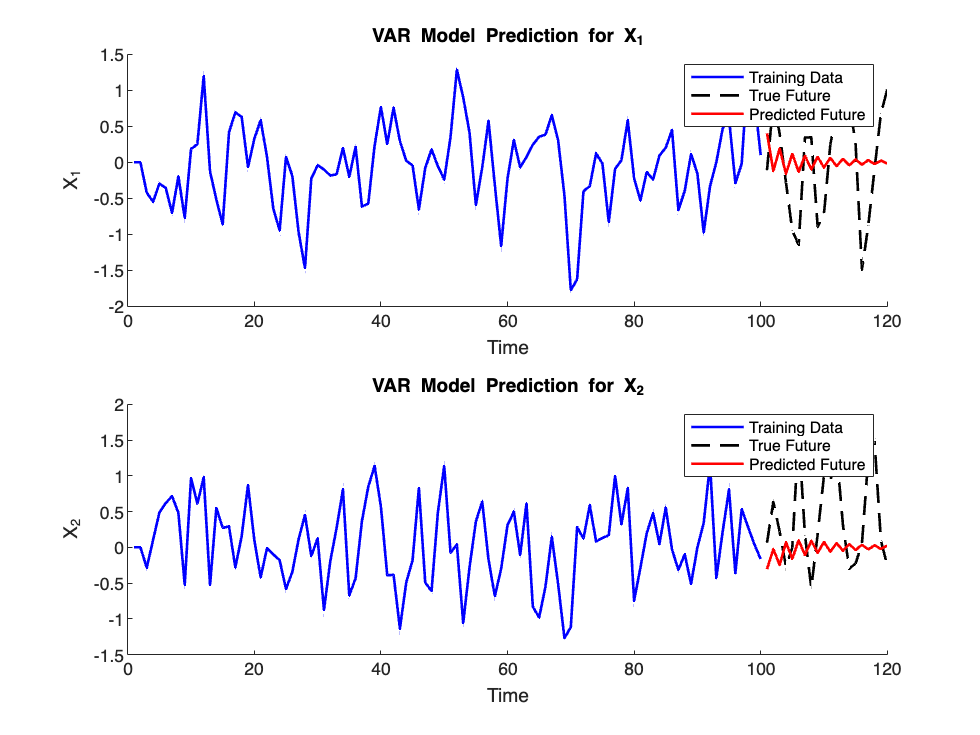


% Use first 100 time points for training
X_train = X(:, 1:100);

% Fit VAR model using least squares
[A_est, X_pred, ~] = VAR_fit(X_train, P);

% Step 4: Predict Future Values (Time Points 101-120)
X_future = zeros(N, T_future);
X_future(:, 1:100) = X(:, 1:100); % Copy known values

for t = 101:T_future
    X_input = reshape(X_future(:, t-P:t-1), [], 1); % Stack past P values
    X_future(:, t) = A_est * X_input;  % Predict next step
end

% Extract true vs. predicted future values (101-120)
X_pred_future = X_future(:, 101:T_future);
X_actual_future = X(:, 101:T_future);

% Plot actual vs. predicted time series
figure;
for i = 1:N
    subplot(N,1,i);
    hold on;
    plot(1:100, X(i,1:100), 'b', 'LineWidth', 1.5); % Actual data
    plot(101:120, X_actual_future(i,:), '--k', 'LineWidth', 1.5); % True future
    plot(101:120, X_pred_future(i,:), 'r', 'LineWidth', 1.5); % Predicted future
    title(['VAR Model Prediction for X_', num2str(i)]);
    xlabel('Time'); ylabel(['X_', num2str(i)]);
    legend('Training Data', 'True Future', 'Predicted Future');
    hold off;
end